# IV curve recursive algorithm

Macabebe and Van Dyk, 2008, DOI 10.1002/pssc.200776834

clearvars
close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

Import

LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\01_IV_curve_chip_spento.txt';

CONVERSION = 50e3; % Ohm (50 kOhm because probably the resistance levers were in the position that michle wanted)

ivdata = importdata(LPath, '\t', 1);
V = ivdata.data(:, 1);
I = ivdata.data(:, 2)*100/CONVERSION; % mA/cm2

I = I + abs(I(V == 0));
I(V == 0)

ans = 0

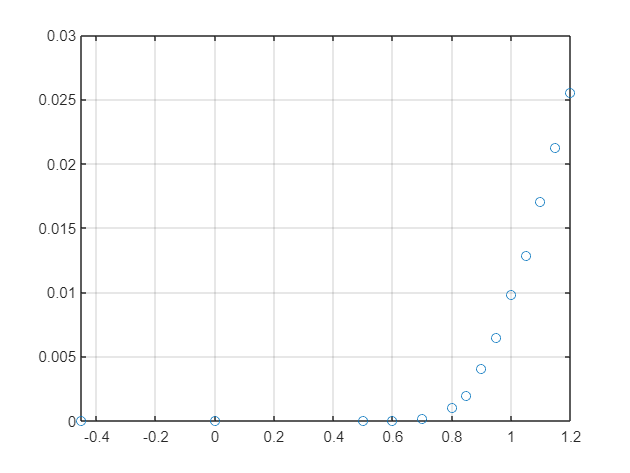

% Plot
figure()
plot(V, I, 'o')
xlim([min(V) max(V)])
grid()

## Initial values for the parameters

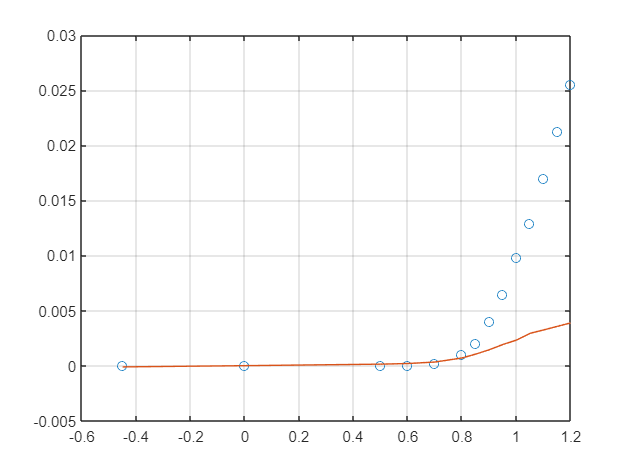

I010 = 2e-8;
Rs0 = 10;
Rsh0 = 4e3;
alpha10 = 1/0.026/3;
I020 = 2e-10;
alpha20 = 1/0.026/5;
p0 = [I010, Rs0, Rsh0, alpha10, I020, alpha20];

Ifit0 = twodiodemodel(V, I, p0);
figure()
plot(V, I, 'o')
% xlim([min(V) max(V)])
hold on
plot(V, Ifit0)
grid()

## Initialization

pVary = [2e-11 - 1e-12, Rs0, 1e5, 5];
npStep = [3, 7, 2, 2];

pArr = struct('I0', zeros(1, npStep(1)), ...
    'Rs', zeros(1, npStep(2)), ...
    'Rsh', zeros(1, npStep(3)), ...
    'alpha', zeros(1, npStep(4)));
pFields = fieldnames(pArr);
for iF = 1:numel(pVary)
    f = pFields{iF};
    pArr.(f) = linspace(p0(iF) - pVary(iF), p0(iF) + pVary(iF), npStep(iF));
end

## Fit

Tol = 1e-4;
alphas = pArr.alpha;
Res4D = ones(npStep);
wbar = waitbar(0, 'Performing Macabebe-Van Dyk algorithm', ...
    'Name', 'Fit in progress');
for iI0 = 1:npStep(1)
    I0_ = pArr.I0(iI0);
    for iRs = 1:npStep(2)
        Rs_ = pArr.Rs(iRs);
        for iRsh = 1:npStep(3)
            Rsh_ = pArr.Rsh(iRsh);
            Res = Res4D(iI0, iRs, iRsh, :);
            parfor ialpha = 1:npStep(4)
                alpha_ = alphas(ialpha)
                p_ = [I0_, Rs_, Rsh_, alpha_];
                Ifit_ = onediodemodel(V, I, p_);
                Res(ialpha) = rms(I - Ifit_);
            end
                Res4D(iI0, iRs, iRsh, :) = Res;
                wbarRatio = ((iI0 - 1)*npStep(2)*npStep(3)*npStep(4) + ...
                (iRs - 1)*npStep(3)*npStep(4) + ...
                iRsh*npStep(4))/(npStep(1)*npStep(2)*npStep(3)*npStep(4));
            waitbar(wbarRatio, wbar)
        end
    end
end
delete(wbar)

[minval, minidx] = min(Res4D(:))

minval = 1.6656e-04

minidx = 58

[i, j, k, l] = ind2sub( size(Res4D), minidx )

i = 1

j = 6

k = 1

l = 2

mod(unrollIdx - 2, npStep(1))

ans = 2

Ifit_ = onediodemodel(V, I, p_);
Residuals = rms(I - Ifit_)

Residuals = 1.6656e-04

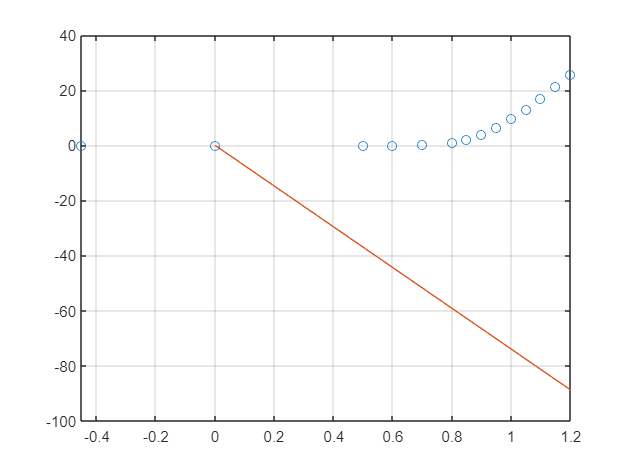

II = linspace(0, 30, 1000);
VV = linspace(0, 1.2, 1000);
diff = 2;
toll = 1;
while diff < tol
    I_ = onediodemodel(VV, II, p0);

end

figure()
plot(V, I, 'o')
xlim([min(V) max(V)])
hold on
plot(VV, Ifit0)
grid()

function Ifit = onediodemodel(V, I, p)
    % p = [I0, Rs, Rsh, alpha]
    Idiode = p(1)*(exp(p(4)*(V - I*p(2))) - 1);
    Ish = (V - I*p(2))/p(3);
    Ifit = Idiode + Ish;
end
function Ifit = twodiodemodel(V, I, p)
    % p = [I01, Rs, Rsh, alpha1, I02, alpha2]
    Idiode1 = p(1)*(exp(p(4)*(V - I*p(2))) - 1);
    Idiode2 = p(5)*(exp(p(6)*(V - I*p(2))) - 1);
    Ish = (V - I*p(2))/p(3);
    Ifit = Idiode1 + Idiode2 + Ish;
end